2023/09/15

Lecture 2

Beginnin with Euler's method for ODEs

1.Newton's first Law

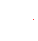

%def
m = 70;
g = 9.81;
c = 12.5;
t = 0:0.1:20;

v = (g*m/c)*(1-exp(-c*t/m));
h = plot(t,v,'r-');
set(h,'linewidth',2);
xlabel('Time(sec)','FontSize',20);
ylabel('Velocity(m/s)','FontSize',20);

2.Exercise

2.1.Write a program script in Matlab that calculates Euler’s solution to a first order differential equation (see the exercise description for details)

2.2. Calculate the largest step size ℎ for which the error between Euler’s solution and the analytic solution is no larger than 5% of the analytic solution at any time over the given interval (see the exercise description for details) 

2.3.This time you will submit your code (.m file(s)) separately from the online copy in the embedded matlab on Blackboard.

h = 0.5;

x = 0 : h : 4.0;
n = length(x);
y = zeros(1,n);

y(1) = 1;

for i = 1: n - 1
  slope = differential(x(i));
  y(i+1) = y(i) + slope * h;
end

Unrecognized function or variable 'differential'.


function differential 
